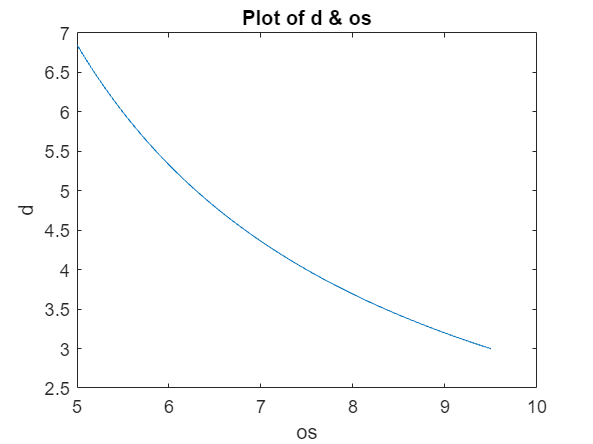

clc;
clear ;
a=0;
b=15;
g = 9.81;
of = 1.5;
iteration = 30;
d = zeros (1,90);
i = 1;
svalues = zeros(1,90);
for os = 5 : 0.05 : 9.5
f =@(d) sqrt((3*g*d)*(os-of)/of) - 21.69;
d(i) = InPlace(f,a,b,iteration);
svalues(1,i)  = os;
i = i + 1;
end
plot(svalues,d);
xlabel('os');
ylabel('d');
title('Plot of d & os');

function[output] = InPlace(f,a,b,iteration)
    for i = 1 : iteration
    ai = a;
    bi = b;
    ri = (ai*(eval(subs(f,bi))) - bi*(eval(subs(f,ai))))/((eval(subs(f,bi))) - (eval(subs(f,ai))));
    if(eval(subs(f,ri))==0)
        break;
    elseif ((eval(subs(f,ri))*eval(subs(f,ai)))>0)
       a = ri;
    else
       b = ri;  
    end
    end
    output = ri;
end
